# TEST 1


rng('shuffle')

x0=5; xf=15; y0=5*randn  

y0 = -7.3293


[x,y]=RK4(@Prob1,[x0,xf],y0,.01);

%y'=y^2*(3-y)/(x^2+1),  5<=x<=15,  y(5)=y0.
Prob1(xf,y0)

ans = 2.4552

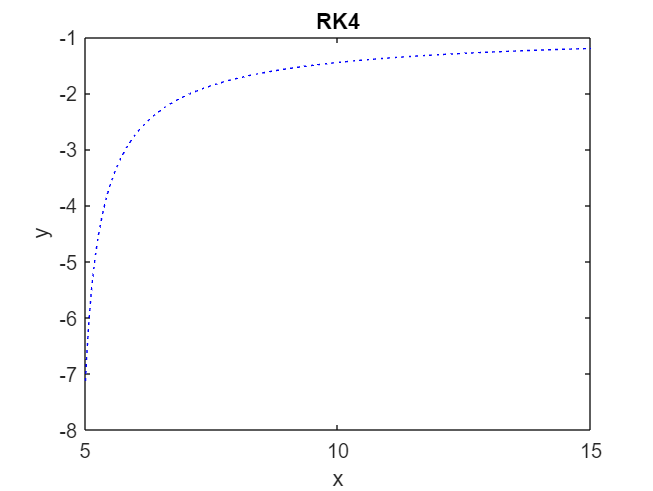


plot(x,y,'b:')
hold on
xlabel('x')
ylabel('y')
title('RK4')
hold off

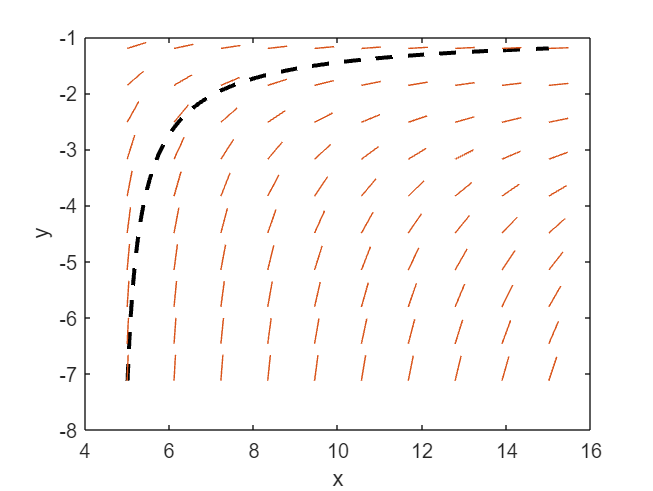


plot(x,y,'k--','LineWidth',2)
hold on
[X,Y]=meshgrid(linspace(x0,xf,10),linspace(min(y),max(y),10));
DY=(Y.^2.*(3-Y))./(X.^2+1); %DY is rhs of original equation
DX=ones(size(DY));
DW=sqrt(DX.^2+DY.^2);
quiver(X,Y,DX./DW,DY./DW,.4,'.');
xlabel('x');
ylabel('y');
hold off

function dy= Prob1(x,y)
%y'=y^2*(3-y)/(x^2+1),  5<=x<=15,  y(5)=y0.
dy=(y.^2*(3-y))/(x.^2+1);
end